# Midterm 2 - Take Home Portion

## Amelia Rotondo, CWID: 887925113

Note: the functions that had to be created throughout this exam are all listed at the bottom so that they can be used throughout this script. 

### Problem 1: 

% Initial Data
y = [1910, 1920, 1930, 1940, 1950, 1960, 1970, 1980, 1990, 2000, 2010];
p = [91.97, 105.71, 122.78, 131.67, 151.33, 179.32, 203.30, 226.54, 248.72, 281.42, 308.75];
yy = min(y):1:2030;

% Setting up the Graph
figure(1); clf; hold on; grid on;
xlabel('Year');
ylabel('Population (millions)');
xlim([1900, 2040]);
ylim([-100, 500]);
title('Amelia R - Problem 1 Plot');
legend('Location', 'best');

### Part 1.a:

% Plot the Data
plot(y, p, 'ko', 'DisplayName', 'Original Data');

% Plot the Educated Guess
plot(2030, 378.75, 'bo', 'DisplayName', 'Educated Guess');

**My educated guess for the population in year 2030 is 378.75.**

    I derived this guess by taking the rounded difference between the 2010 and 2000 population (28), multiplying it by 2 (56), and adding it to the rounded difference between the 1920 and 1910 (14). I took this approach since the points appear to depict exponential growth, and I figured this was a quick and easy way to develop an educated guess. My work is shown below: 

    
$$308.75 + 2(309-281) + (106-92)\\
= 308.75 + 2(28) + 14\\
= 378.75
$$


### Part 1.b: 

% Least Squares Solution - Degree 7 
ls7 = polyfit(y, p, 7);

pp7 = polyval(ls7, yy);

% Find Doomsday (Real Roots of ls7)
doom7 = roots(ls7);
doom7 = doom7(imag(doom7) == 0);

% Plot Results 
plot(yy, pp7, 'y-', 'DisplayName', 'Least Squares: Degree 7', 'LineWidth', 2);
plot(doom7, polyval(ls7, doom7), 'b*', 'DisplayName', 'Doomsday - Degree 7');
fprintf('Doomsday Date (mm/dd/yyyy): %s\n', decimalToDate(doom7));

Doomsday Date (mm/dd/yyyy): 04/03/2025


    Please Note that decimalToDate is a simple function I made for the purposes of this conversion. I will not be including it in my script because it does not feel very relevant to the assignment at hand. 

### Part 1.c: 

% Least Squares Solution - Degrees 1 and 2
ls1 = polyfit(y, p, 1);
ls2 = polyfit(y, p, 2);
pp1 = polyval(ls1, yy);
pp2 = polyval(ls2, yy);

% Find Estimates for Year 2020 
est1 = polyval(ls1, 2020);
est2 = polyval(ls2, 2020);

% Plot Results 
plot(yy, pp1, 'g-', 'DisplayName', 'Least Squares: Degree 1');
plot(yy, pp2, 'm-', 'DisplayName', 'Least Squares: Degree 2');
fprintf('2020 Predictions:\nDegree 1: %.9f\nDegree 2: %.9f\n', est1, est2);

2020 Predictions:
Degree 1: 317.752000000
Degree 2: 342.841393939


### Part 1.d: 


$$P(t) = \frac{L}{1 + Ce^{\alpha t}}\\
\frac{L}{P(t)} =1 + Ce^{\alpha t}\\
ln(\frac{L}{P(t)} - 1)= {\alpha t} + ln(C)\\$$


% Initial Values 
L = 8e8; 
logFunc = @(t, C, alpha) L ./ (1+C.*exp(alpha.*t))

logFunc = function_handle with value:
    @(t,C,alpha)L./(1+C.*exp(alpha.*t))


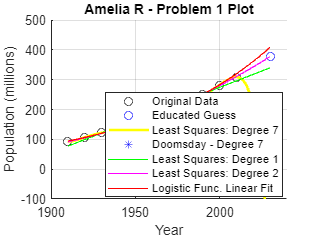


% Fitting the Logistic Function
Y = y; 
P = log((L ./ p) - 1);
AC = polyfit(Y, P, 1);
alpha = AC(1);
C = exp(AC(2));

% Evaluating the Linear Fit 
PP = logFunc(yy, C, alpha);

% Plot Results
plot(yy, PP, 'r-', 'DisplayName', 'Logistic Func. Linear Fit');
hold off; 


% Analysis of year 2000 prediction: 
y2000_diff = p(10) - [polyval(ls1, 2000), polyval(ls2, 2000), polyval(ls7, 2000), logFunc(2000, C, alpha)]

y2000_diff =     7.4184    1.6285   -0.4941   -1.4763


fprintf('Difference Between p(2000) and Estimates:\nDegree 1     :%.9f\nDegree 2     :%.9f\nDegree 7     :%.9f\nLogistic Fit :%.9f\n', abs(y2000_diff(:)));

Difference Between p(2000) and Estimates:
Degree 1     :7.418363636
Degree 2     :1.628503497
Degree 7     :0.494062500
Logistic Fit :1.476315457


**The Estimate I have the most faith in is the Fit of the Logistic Function. **

    While the Degree 7 Least Squares Estimation provides the most accurate estimate for the year 2000 population, it's clear by the existence of doomsday that this is not the best model for estimating future population growth. Therefore, the closest estimate for the year 2000 that still provides good estimates for future population growth is the fit of the logistic function. 

### Problem 2: 


$$\[ \lim_{x\to\infty} \frac{\pi(x)}{x/ln(x)} = 1\]
\[\text{Li} =  \int_{a}^{b} x^2 \,dx \]
\[\pi(x) \sim \frac{x}{ln(x)}\]$$


% Tool for Testing Error 
actualPrimes = @(x) length(primes(x));
maxval = 100000;
xx = 2:1:maxval; 

% Testing actualPrimes(x)
yy_primes = zeros((maxval-1), 1);
tic; 
for x = xx 
    yy_primes(x-1) = actualPrimes(x);
end
toc;

Elapsed time is 12.993200 seconds.



primeMax = actualPrimes(maxval);

### Part 2.a: 

% Testing piFunc(x)
yy_pi = zeros((maxval-1), 1);
tic;
for x = xx 
    yy_pi(x-1) = piFunc(x);
end
toc;

Elapsed time is 0.070785 seconds.



piMax = piFunc(maxval);
primeDiff100k = abs(piMax - primeMax);
fprintf('Actual Error of Pi(x): %.9f\n', primeDiff100k);

Actual Error of Pi(x): 906.110361935


    Please note that the design of `piFunc()` can be located at the end of this script, since that allows me to use it throughout the rest of this script. 

### Part 2.b: 

% Testing Li(x)
yy_li = zeros((maxval-1), 1);
tic;
for x = xx 
    yy_li(x-1) = Li(x);
end
toc; 

Elapsed time is 2.578596 seconds.



liMax = Li(maxval);
primeDiff100k = abs(liMax - primeMax);
fprintf('Actual Error of Li(x): %.9f\n', primeDiff100k);

Actual Error of Li(x): 37.315558556


    Please note that the design of `Li()` can be located at the end of this script, since that allows me to use it throughout the rest of this script. 

**    For the development of Li(x) I chose to implement the matlab **`trapz()`** function with three uneven subdivisions. **Since $\frac{1}{t}$ becomes smoother as $t$ gets larger, I implemented a geometric ratio to calculate a given number of subintervals that get geometrically larger based on the amount of subdivisions. Since this further divided the integral, it allows the `trapz()` method to very accurately approximate larger values of x along the integral. Additionally, `trapz()` provides a very accurate estimate of the integrand considering that it is relatively smooth in contrast to higher-degree polynomials. 

### Part 2.c:

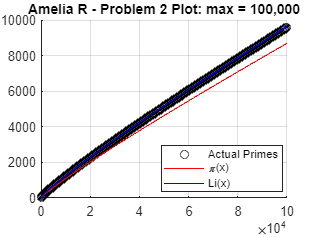

% Setting up the Graph 
figure(2); clf; hold on; grid on;
title('Amelia R - Problem 2 Plot: max = 100,000');
legend('Location', 'best');

% Plot Functions up to 100,000 (maxval)
plot(xx, yy_primes, 'ko', 'DisplayName', 'Actual Primes');
plot(xx, yy_pi, 'r-', 'DisplayName', '\pi(x)');
plot(xx, yy_li, 'b-', 'DisplayName', 'Li(x)');
hold off; 


% Going Up to 1 Million: 
maxval = 1000000;
xx = 2:1:maxval; 

% Pi(x) Evaluation
yy_pi = zeros((maxval-1), 1);
tic;
for x = xx 
    yy_pi(x-1) = piFunc(x);
end
toc;

Elapsed time is 0.628668 seconds.



% Li(x) Evaluation
yy_li = zeros((maxval-1), 1);
tic;
for x = xx 
    yy_li(x-1) = Li(x);
end
toc; 

Elapsed time is 25.618025 seconds.


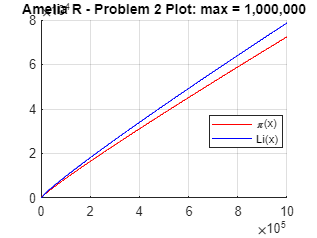


% Setting up the Graph 
figure(3); clf; hold on; grid on;
title('Amelia R - Problem 2 Plot: max = 1,000,000');
legend('Location', 'best');

% Plot Functions up to 1,000,000 (maxval)
plot(xx, yy_pi, 'r-', 'DisplayName', '\pi(x)');
plot(xx, yy_li, 'b-', 'DisplayName', 'Li(x)');
hold off; 


% Print pi(x)/(x/ln(x))
x = 1e12;
verify_pi = piFunc(x)/(x/log(x)); 
fprintf('as x = 1e12, pi(x)/(x/log(x)) = %.9f\n', verify_pi);

as x = 1e12, pi(x)/(x/log(x)) = 1.000000000


    I would like to note that when I tried to run this 1 billion times my computer ran into timeout errors. Therefore, I will only be providing the plot up to one-million. Additionally, when trying to calculate the Actual Primes for max = 1,000,000 I ran into more timeout issues, hence they are not provided. 

    As shown in the printed response, as x gets very large, $\[ \ \frac{\pi(x)}{x/ln(x)} = 1\]$. 

   **As shown in the graph where maxval = 100,000 , Li(x) appears to better represent the actual prime values than pi(x) does. **

### Part 2.d (BONUS): 

    I am not doing this right now, but it's cool to think about. I am excited to see the actual solution for this section. 

### Problem 3:

% Initial Data 
epsilon = 0.008;
a = 0.139;
gamma = 2.54;

% Fitzhugh-Nagumo Equations 
dvdt = @(v, w, I) I - v*(v-a)*(v-1)-w;
dwdt = @(v, w) epsilon*(v-gamma*w);
dYdt = @(t, Y, I) [dvdt(Y(1), Y(2), I); dwdt(Y(1), Y(2))];

### Part 3.a: 

% Given Fixed Point Function
f = @(v, I) I - v * (v - a) * (v - 1) - v / gamma;

% Arrays for Fixed Points
v_fixed_points = zeros(11, 1);
w_fixed_points = zeros(11, 1);

% Generate Fixed Points for Several I-Values
for i = 1:11
   I = (i-1)*0.1; 

    % Find Zeroes of the Equation
    v_fixed = fzero(@(v) f(v, I), [0, 2]);

    % Calculate w using v
    w_fixed = v_fixed / gamma;
    
    % Verify that v and w are Fixed Points
    if(dYdt(1, [v_fixed, w_fixed], I) < [eps; eps])

        % Store the fixed points
        v_fixed_points(i) = v_fixed;
        w_fixed_points(i) = w_fixed;
    end    
end

% Display Results
disp('Fixed points for I = 0:0.1:1:');

Fixed points for I = 0:0.1:1:


disp(table((0:0.1:1)', v_fixed_points, w_fixed_points, 'VariableNames', {'I', 'v', 'w'}));

     I        v          w   
    ___    _______    _______

      0          0          0
    0.1    0.44832     0.1765
    0.2    0.78496    0.30904
    0.3    0.91512    0.36028
    0.4      1.005    0.39566
    0.5     1.0758    0.42356
    0.6     1.1353    0.44697
    0.7      1.187    0.46733
    0.8     1.2331    0.48548
    0.9     1.2749    0.50192
      1     1.3132    0.51702



    As shown by the script and table included, the fixed point is a solution to the equations provided, and there is exactly one unique fixed point for any I greater than or equal to zero. 

### Part 3.b: 


$$J =   \pmatrix{\frac{\partial (I - v(v-a)(v-1) - w)}{\partial v} & \frac{\partial (I - v(v-a)(v-1) - w)}{\partial w} \cr
\frac{\partial (\epsilon(v-\gamma w))}{\partial v} & \frac{\partial (\epsilon(v-\gamma w))}{\partial w}}\\

J =   \pmatrix{-3v^2 + 2(1 + a)v - a & -1 \cr
    \epsilon & -\epsilon \gamma}}\\$$


% Showing off the use of findEig 
I = 0.1; 
eigs = findEigs(I, epsilon, a, gamma);
disp(eigs);

    0.2497
    0.0093



    Please note that `eigFind()` is defined at the bottom of this script so that it can be used throughout this script. 

### Part 3.c:

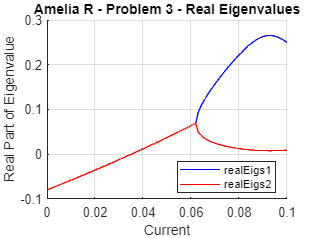

% Given Parameters
I = 0:0.001:0.1;

% Arrays for Real Eigenvalues
realEigs1 = zeros(length(I), 1);
realEigs2 = zeros(length(I), 1);

% Loop over I values and calculate eigenvalues
for i = 1:length(I)

    % Find Eigenvalues
    eigs = findEigs(I(i), epsilon, a, gamma);
    
    % Store Real Parts of Eigenvalues
    realEigs1(i) = real(eigs(1));
    realEigs2(i) = real(eigs(2));
end

% Plot Results
figure(4); clf; hold on; grid on; 
plot(I, realEigs1, 'b-', 'DisplayName', 'realEigs1');
plot(I, realEigs2, 'r-', 'DisplayName', 'realEigs2')
title('Amelia R - Problem 3 - Real Eigenvalues');
xlabel('Current');
ylabel('Real Part of Eigenvalue');
legend('Location', 'best');
hold off; 

### Part 3.d:

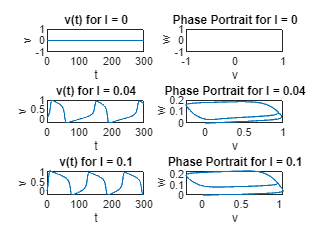

% Given Parameters
tspan = [0, 300]; 
Y0 = [0, 0];
I_func = @(t, I_value) I_value * (t <= 5);
I = [0, 0.04, 0.1];

% Iteratively Generate Sub-Plots
figure(5); clf; hold on; 

for i = 1:length(I)
    % Solve ODE
    [t, Y] = ode45(@(t, Y) dYdt(t, Y, I(i)), tspan, Y0);
    
    % Plot v(t)
    subplot(length(I), 2, 2*i-1);
    plot(t, Y(:, 1));
    title(['v(t) for I = ', num2str(I(i))]);
    xlabel('t');
    ylabel('v');
    
    % Plot Phase Portraits
    subplot(length(I), 2, 2*i);
    plot(Y(:, 1), Y(:, 2));
    title(['Phase Portrait for I = ', num2str(I(i))]);
    xlabel('v');
    ylabel('w');
end

**    Given what we found in part 3.a, we can infer that the results of our graphs make sense. **Since I = 0 implies v and w = 0, it's fair that there would be no phase portrait, and that v(t) = 0. With I = 0.04 or 0.1, v(t) appears to oscillate in a jagged motion, and the phase portrait depicts the stability of the system. Furthermore, using the information given in 3.a, we can infer that in all 3 of these examples the system is stable. In addition, we can interpret the equation $w = v/\gamma$ to understand that w will always be less than v for some $\gamma > 1$. This further explains how the phase portraits appear to be squished along the y-axis, showing how the values of v are much larger than the values for w. 

### (EXTRA FUNCTIONS): 

**2.a: **function for pi(x): 

function pi_x = piFunc(x)
    % approximates the num of primes less than or equal to the x_value
    
    % Bounds-Checking
    if x < 2
        pi_x = 0;
        return;
    end
    
    % Compute pi(x)
    f = @(x) x ./ log(x);
    pi_x = f(x);
end

**2.b: **function for Li(x):

function li_x = Li(x)
    % approximates the number of primes less than or equal to x
    
    % Bounds-Checking
    if x < 2
        li_x = 0;
        return;
    end

    % Integrand
    intFunc = @(t) 1./log(t);

    % Calculate SubIntervals
    intervals = 3;
    ratio = (x/2)^(1/intervals); 
    subintervals = 2 * (ratio.^(0:intervals));
    subintervals(end) = x;
    

    % Initialize li_x
    li_x = 0;

    % Calculate Integral over each subinterval
    for k = 1:length(subintervals) - 1
        xx = linspace(subintervals(k), subintervals(k+1), 100);
        yy = intFunc(xx);
        li_x = li_x + trapz(xx, yy);
    end
end

**3.b: **function to return eigenvalues of fixed point for any input I 

function eigenvalues = findEigs(I, epsilon, a, gamma)

    % Find Fixed Point
    f = @(v, I) I - v * (v - a) * (v - 1) - v / gamma;
    v_fixed = fzero(@(v) f(v, I), [0, 2]);

    % Jacobian Matrix at the Fixed Point
    J11 = -(3*v_fixed^2 - 2*(1+a)*v_fixed + a); 
    J12 = -1;                                   
    J21 = epsilon;                              
    J22 = -epsilon*gamma;                       
    Jacobian = [J11, J12; J21, J22];

    % Eigenvalues of the Jacobian
    eigenvalues = eig(Jacobian);
end
